## Analysis Dataset 2: steady-state Visual Evoked Potential (ssVEP) of fear conditioning

The following script shows how dataset 2 was analyzed using the time-GAL toolbox. EEG data can be retrieved from the OSF repository (https://osf.io/q56ns/) and found in folder "Dataset2_FearConditioning_ssVEP".

#### Import/group data

The time-GAL toolbox needs data to be formated in a specific way: One 3D (matrix channels, time, trials) and one vector indicating subject's id of each trial. These matrix and vector are needed for each condition. Here, we show the example with fearful cue (CS+) during habituation vs. extinction phases:

[Data_Condition_HabituationCSp, List_Condition_HabituationCSp] = groupCondition('./Dataset2_FearConditioning_ssVEP/', 'HabituationCSp', 'Data', 'FileName', 'Condition_HabituationCSp');


 
 A total of 31 files were found with tag: HabituationCSp    Data: [129×1501×8 double]


 Reading file: Data_HabituationCSp_subject_1.mat | File 1 out of 31
 Reading file: Data_HabituationCSp_subject_10.mat | File 2 out of 31
 Reading file: Data_HabituationCSp_subject_11.mat | File 3 out of 31
 Reading file: Data_HabituationCSp_subject_12.mat | File 4 out of 31
 Reading file: Data_HabituationCSp_subject_13.mat | File 5 out of 31
 Reading file: Data_HabituationCSp_subject_14.mat | File 6 out of 31
 Reading file: Data_HabituationCSp_subject_15.mat | File 7 out of 31
 Reading file: Data_HabituationCSp_subject_16.mat | File 8 out of 31
 Reading file: Data_HabituationCSp_subject_17.mat | File 9 out of 31
 Reading file: Data_HabituationCSp_subject_18.mat | File 10 out of 31
 Reading file: Data_HabituationCSp_subject_19.mat | File 11 out of 31
 Reading file: Data_HabituationCSp_subject_2.mat | File 12 out of 31
 Reading file: Data_HabituationCSp_subject_20.mat | File 13 out of 31
 Reading f

[Data_Condition_ExtinctionCSp, List_Condition_ExtinctionCSp] = groupCondition('./Dataset2_FearConditioning_ssVEP/', 'ExtinctionCSp', 'Data', 'FileName', 'Condition_ExtinctionCSp');


 
 A total of 31 files were found with tag: ExtinctionCSp    Data: [129×1501×11 double]


 Reading file: Data_ExtinctionCSp_subject_1.mat | File 1 out of 31
 Reading file: Data_ExtinctionCSp_subject_10.mat | File 2 out of 31
 Reading file: Data_ExtinctionCSp_subject_11.mat | File 3 out of 31
 Reading file: Data_ExtinctionCSp_subject_12.mat | File 4 out of 31
 Reading file: Data_ExtinctionCSp_subject_13.mat | File 5 out of 31
 Reading file: Data_ExtinctionCSp_subject_14.mat | File 6 out of 31
 Reading file: Data_ExtinctionCSp_subject_15.mat | File 7 out of 31
 Reading file: Data_ExtinctionCSp_subject_16.mat | File 8 out of 31
 Reading file: Data_ExtinctionCSp_subject_17.mat | File 9 out of 31
 Reading file: Data_ExtinctionCSp_subject_18.mat | File 10 out of 31
 Reading file: Data_ExtinctionCSp_subject_19.mat | File 11 out of 31
 Reading file: Data_ExtinctionCSp_subject_2.mat | File 12 out of 31
 Reading file: Data_ExtinctionCSp_subject_20.mat | File 13 out of 31
 Reading file: Data_Ext

Once grouped all data from the folder of subject's files in two conditions data, it is saved on a file and workspace. We can use either the workspace data or load it again in a new session:

% load('Condition_HabituationCSp.mat');
% load('Condition_ExtinctionCSp.mat');

#### Computing time-GAL method

Now, data is ready to be included in the toolbox as input. We use the time-GAL toolbox to compare Habituation vs. Extinction EEG responses to the CS+. To speed-up the MVPA decoding process, we takes advantage of the parallel computing toolbox implemented in MATLAB by using parameters 'ParallelComputing', true and 'ParallelComputingCores', 4. Since 4 channels are facials and we disregard this information, we use the parameter 'Channels' to select the EEG sensors to be used in the analysis. Finally, results are saved in a mat file. Since data is big and we are mainly interested on the post-stimulus part, we select a shorter windows of time, leaving only a pre-stimulus windows of 100 time points (i.e. 200 ms).

timeWindows = [401:1500]

timeWindows =    401   402   403   404   405   406   407   408   409   410   411   412   413   414   415   416   417   418   419   420   421   422   423   424   425   426   427   428   429   430   431   432   433   434   435   436   437   438   439   440   441   442   443   444   445   446   447   448   449   450


[timeGALoutput] = timeGAL(Data_Condition_HabituationCSp, Data_Condition_ExtinctionCSp, List_Condition_HabituationCSp, List_Condition_ExtinctionCSp, ...
    'ParallelComputing', true, 'ParallelComputingCores', 4, ...
    'Channels', [1:124 129], ...
    'Filename', 'resultsTimeGAL_FearConditioning_ssVEP.mat', ...
    'Time', timeWindows)


 1. Initializing function. 

 Using Parallel Computing Toolbox with 4 cores 

Starting parallel pool (parpool) using the 'LocalProfile4cores' profile ...
Preserving jobs with IDs: 4 5 6 7 19 25 26 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile LocalProfile4cores. To create 'myCluster' use 'myCluster = parcluster('LocalProfile4cores')'.
Connected to parallel pool with 4 workers.

 
 2. Computing GAL matrices. Progress:

 Subject: 3 | 3 out of 31  

 Subject: 1 | 1 out of 31  

 Subject: 2 | 2 out of 31  

 Subject: 4 | 4 out of 31  
.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|
 Time elapse: 1 minutes 1.617408e+01 seconds
 Subject: 13 | 13 out of 31  
.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|

timeGALoutput = struct with fields:
    GeneralizationMatrix: [1×1 struct]
       CorrelationMatrix: [1×1 struct]
                 TimeGAL: [1×1 struct]
              Parameters: [1×1 struct]


Once decoding calculations has been computed, results can be found in the variable timeGALoutput both in the workspace and the mat file. We can load it if needed in a different session:

% load('resultsTimeGAL_FearConditioning_ssVEP.mat')

#### Visualization of results

Finally, once time-GAL has been calculated, we can explore the results by visualizing them. All the important data such as GAL, correlation and time-GAL matrices can be found in the timeGALoutput variable (i.e. the file if it was saved). While visualization can be independently crafted by the user, the time-GAL toolbox provides its own function for easiness and convenience. It contains a few parameters to change statistical alpha thresholds, titles, file saving or resolutions, for example. However, for simplicity, here we only use the function fed with the time-GAL output:

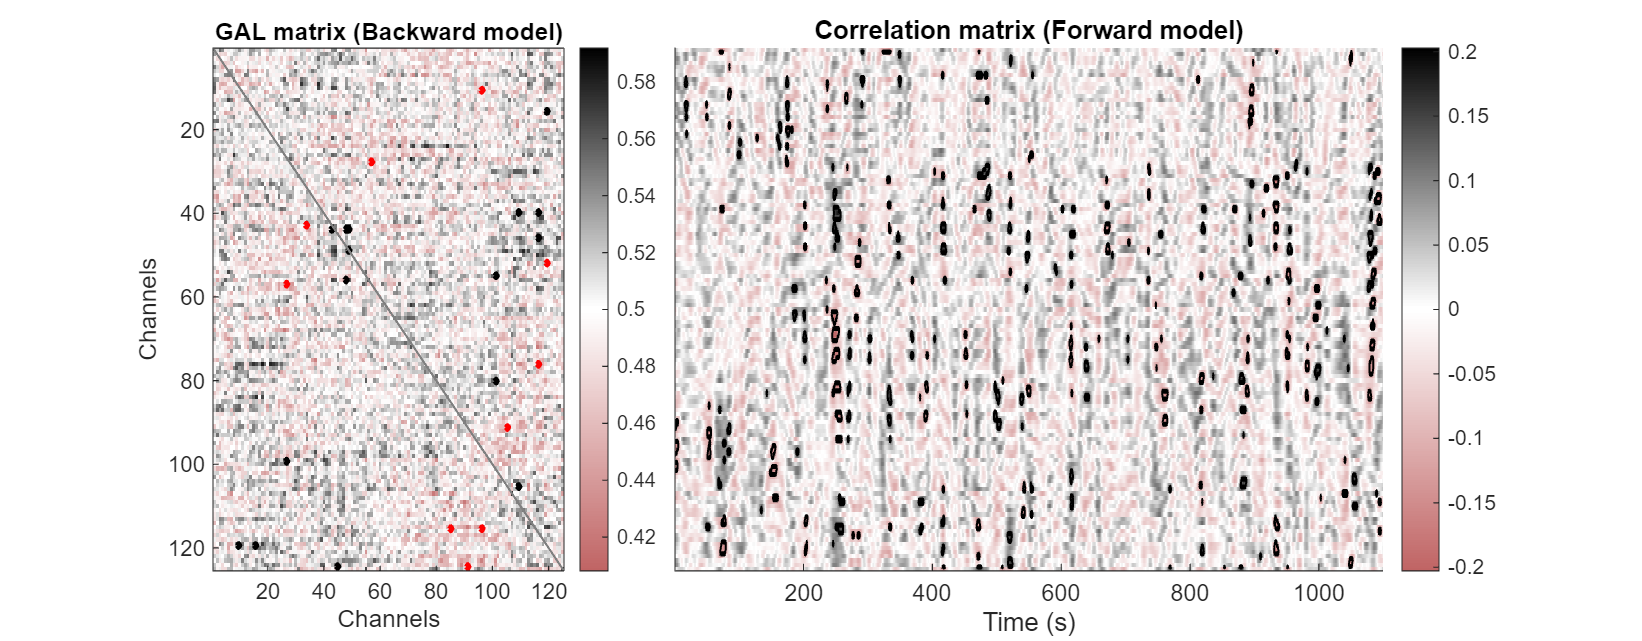

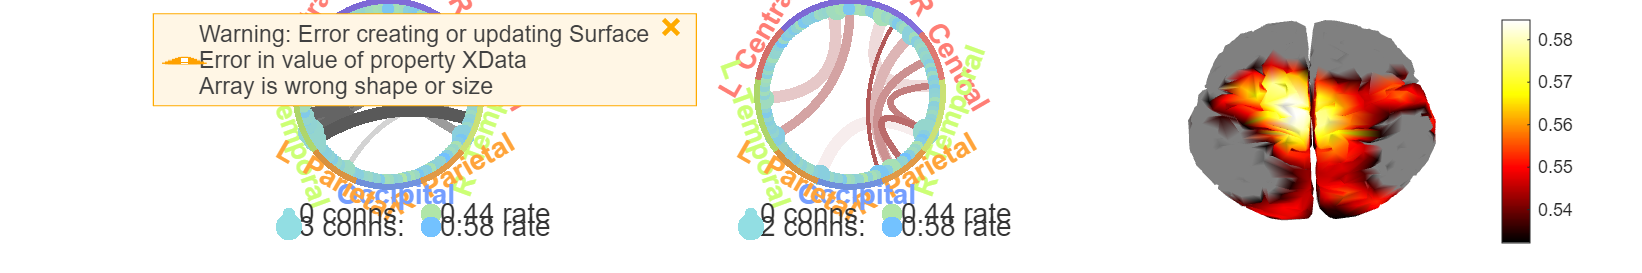

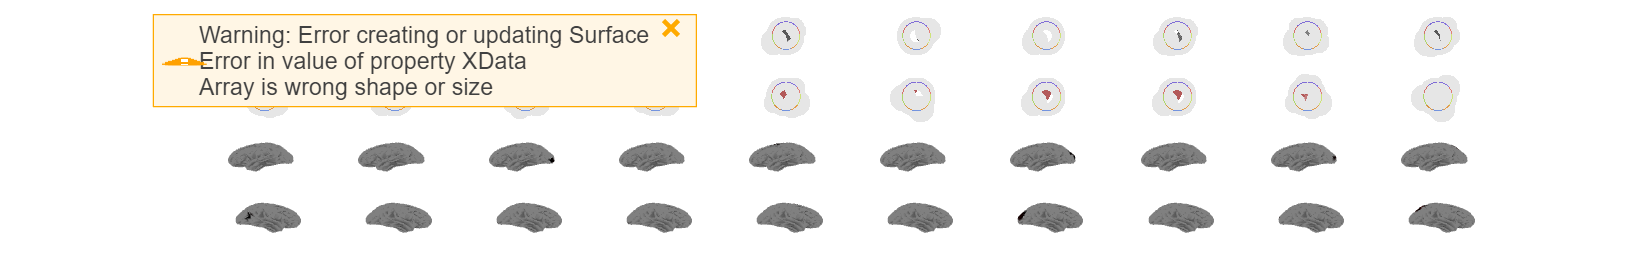

visualizationTimeGAL(timeGALoutput)

This function plots three figures showing (1) the GAL and correlation matrices, (2) the circular connectivity plots and topography, and (3) the time-GAL and topography across the trial.